# Car Economy

The `carEconomy.mat `contains 2,587 car statistics in the U.S. in 2007. Each observation includes 15 measurements related to the particular car, such as weight, engine size, transmission type, as well as a flag for whether the economy measurement is for city or highway driving.

### 0. Load data

Load the data file, `carEconomy.mat.`

load carEconomy.mat

## MATLAB FUNDAMENTAL

### 1. Plot data1 (4)

Plot **'Fuel economy(**`FuelEcon`**)' with respect to 'Rated HP(**`RatedHP`**)'** with circular makers. The plot should be the same as below. **Beware of title, x&y limits, and x&y labels.**

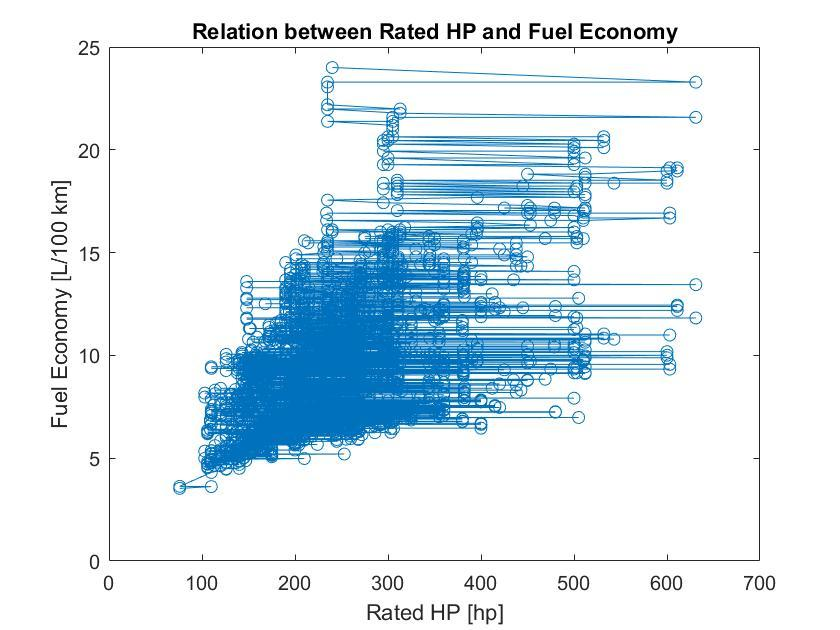

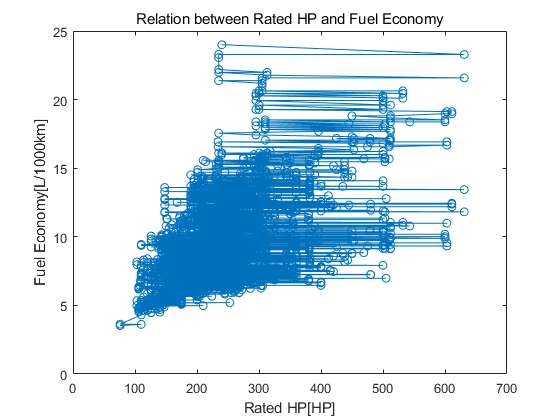

dataset = carEcon;
figure
plot(dataset.RatedHP,dataset.FuelEcon,'o-')
title("Relation between Rated HP and Fuel Economy")
ylabel("Fuel Economy[L/1000km]")
xlabel("Rated HP[HP]")
xlim([0,700])
ylim([0,25])

### 2. Plot data2 (6)

Plot **'Fuel economy(**`FuelEcon`**)' with respect to 'Rated HP(**`RatedHP`**)'** of cars and trucks, with circular and square markers, respectively. The plot should be the same as below. **Beware of title, x&y limits, x&y labels, and legend.**

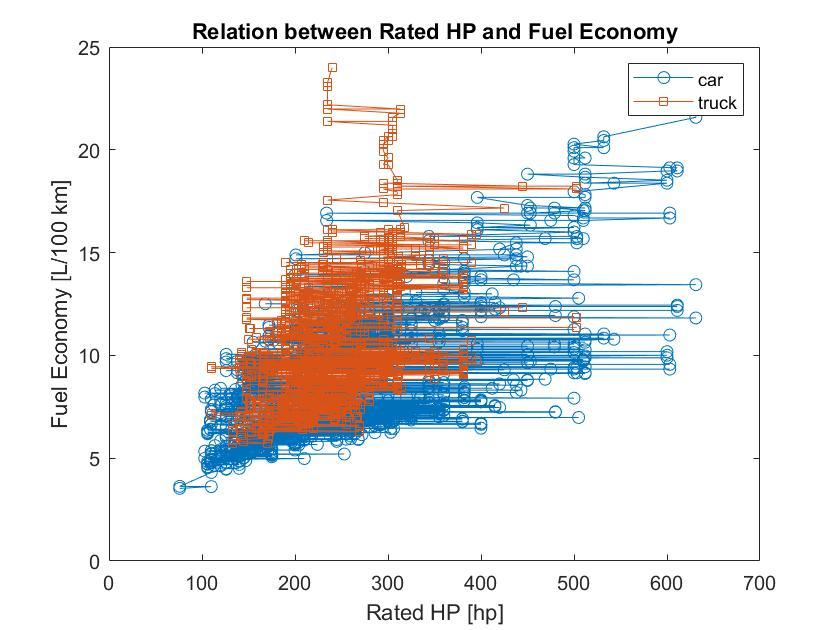

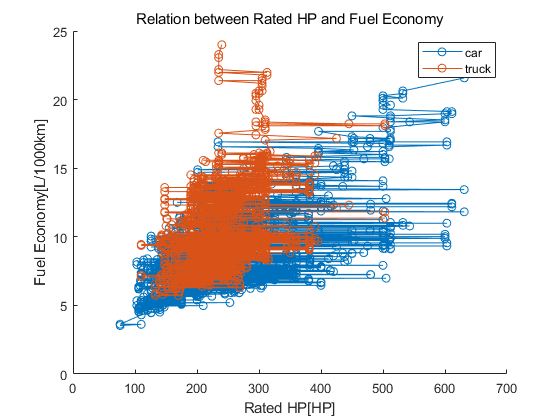

idx_car = carEcon.Car_Truck=="car";
idx_truck = carEcon.Car_Truck=="truck";

dataset_car = dataset(any(idx_car,2),:);
dataset_truck = dataset(any(idx_truck,2),:);

figure
hold on
plot(dataset_car.RatedHP,dataset_car.FuelEcon,'o-')
plot(dataset_truck.RatedHP,dataset_truck.FuelEcon,'o-')
title("Relation between Rated HP and Fuel Economy")
ylabel("Fuel Economy[L/1000km]")
xlabel("Rated HP[HP]")
xlim([0,700])
ylim([0,25])
legend({"car","truck"})
hold off

### 3. Compute power per engine size (4)

Compute the power per engine size (`RatedHP/EngDisp`) and add the results to the table. Name the variable to `HpEngine.`

dataset.HpEngine = dataset.RatedHP./dataset.EngDisp

dataset = 2587×16 table
    Car_Truck    EngDisp    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    AC    PRP    FuelType    City_Highway    Valves_Cyl    FuelEcon    HpEngine
    _________    _______    _______    ____________    _____    ______    ____    _________    ____________    __    ___    ________    ____________    __________    ________    ________

       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N     1         23         city              4          3.5318      50.965 
       car       1.3437       110           AV           F      1417.5    10.8      4.94           29.1        N     31        61         highway           4          3.6187      81.861 
       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N     1         23         highway           4          3.6299      50.965 
       car       1.3437       110       

### 4. Remove an unnecessary variable (4)

Remove `'PRP'` variable from the data and update the table.

dataset.PRP = []

dataset = 2587×15 table
    Car_Truck    EngDisp    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    AC    FuelType    City_Highway    Valves_Cyl    FuelEcon    HpEngine
    _________    _______    _______    ____________    _____    ______    ____    _________    ____________    __    ________    ____________    __________    ________    ________

       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N        23         city              4          3.5318      50.965 
       car       1.3437       110           AV           F      1417.5    10.8      4.94           29.1        N        61         highway           4          3.6187      81.861 
       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N        23         highway           4          3.6299      50.965 
       car       1.3437       110           AV           F      1417.5    1

### 5. Sort by `RatedHP `(4)

Sort the data by `RatedHP` in ascending order and update the table.

dataset = sortrows(dataset,"RatedHP","ascend")

dataset = 2587×15 table
    Car_Truck    EngDisp    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    AC    FuelType    City_Highway    Valves_Cyl    FuelEcon    HpEngine
    _________    _______    _______    ____________    _____    ______    ____    _________    ____________    __    ________    ____________    __________    ________    ________

       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N        23         city              4          3.5318      50.965 
       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N        23         highway           4          3.6299      50.965 
       car       1.6059       103           M5           F      1304.1     9.5      3.84           41.1        Y        23         highway           4          4.9939      64.137 
       car       1.6059       103           A4           F      1304.1     

### 6. How many cars or trucks have fuel economy between 10 and 12 (L/100km)? (4)

fprintf("The number of cars or trucks that have fuel economy between 10 and 12 is")

The number of cars or trucks that have fuel economy between 10 and 12 is

idx = dataset.FuelEcon>=10&dataset.FuelEcon<=12;
sum(sum(idx==1))

ans = 450

### 7. How many cars or trucks are front wheel drive? (4)

(note: In `'Drive'` variable, F = front wheel drive, R = rear wheel drive, 4 = 4 wheel drive)

idx_F = dataset.Drive  =='F';
fprintf("The number of front wheel drive is")

The number of front wheel drive is

sum(sum(idx_F==1))

ans = 834

### 8. List the categories in `'Transmission'` variable (4 = 3 + 1)

    8.1. List the categories in `'Transmission'` variable

categories(dataset.Transmission)

ans = 17×1 cell 배열
    {'A4'}
    {'A5'}
    {'A6'}
    {'AV'}
    {'C6'}
    {'L4'}
    {'L5'}
    {'L6'}
    {'L7'}
    {'L8'}
    {'M4'}
    {'M5'}
    {'M6'}
    {'S4'}
    {'S5'}
    {'S6'}
    {'S7'}


    8.2. How many cars or trucks have L6 transmission?

idx_L6 = dataset.Transmission =='L6';
fprintf("The number of cars or trucks that have L6 transmission is")

The number of cars or trucks that have L6 transmission is

sum(idx_L6==1)

ans = 379

### 9. Extract data that meets the criterion (10)

Extract data(`Car_Truck, AxleRatio, FuelType`) that meets Q6, Q7 and Q8.2. Create a new table (`carFiveFourL6`).

fprintf("Get the whole data.")

Get the whole data.

carFiveFourL6= dataset;
fprintf("Get elements that have fuel economy between 10 and 12.")

Get elements that have fuel economy between 10 and 12.

carFiveFourL6 = carFiveFourL6(any(idx,2),:)

carFiveFourL6 = 450×15 table
    Car_Truck    EngDisp    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    AC    FuelType    City_Highway    Valves_Cyl    FuelEcon    HpEngine
    _________    _______    _______    ____________    _____    ______    ____    _________    ____________    __    ________    ____________    __________    ________    ________

      car        1.9992       126           A4           F      1474.2    10.8      3.85           41.5        Y        23           city            4          10.052      63.024 
      truck      2.2942       143           L5           R      1530.9     9.7       4.1             39        Y        61           city            4          10.052      62.331 
      truck      2.2942       143           L5           R      1530.9     9.7       4.1             39        Y        61           city            4          10.052      62.331 
      truck      2.2942       143           L5           R      1644.3

idx_F = carFiveFourL6.Drive =='F';
fprintf("Get elements that have drive eqal to 'F'.")

Get elements that have drive eqal to 'F'.

carFiveFourL6 = carFiveFourL6(any(idx_F,2),:)

carFiveFourL6 = 122×15 table
    Car_Truck    EngDisp    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    AC    FuelType    City_Highway    Valves_Cyl    FuelEcon    HpEngine
    _________    _______    _______    ____________    _____    ______    ____    _________    ____________    __    ________    ____________    __________    ________    ________

      car        1.9992       126           A4           F      1474.2    10.8      3.85           41.5        Y        23           city            4          10.052      63.024 
      truck      2.4253       150           L4           F      1927.8     9.4      2.69           34.9        Y        61           city            6           10.79      61.848 
      car        2.9825       155           L4           F      1644.3     9.7      3.96           36.3        Y        61           city            6          10.643      51.971 
      car        2.2942       157           L4           F        1701

idx_L = carFiveFourL6.Transmission =='L6';
fprintf("Get elements that have 'L6' transmission.")

Get elements that have 'L6' transmission.

carFiveFourL6 = carFiveFourL6(any(idx_L,2),:)

carFiveFourL6 = 20×15 table
    Car_Truck    EngDisp    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    AC    FuelType    City_Highway    Valves_Cyl    FuelEcon    HpEngine
    _________    _______    _______    ____________    _____    ______    ____    _________    ____________    __    ________    ____________    __________    ________    ________

      car        2.9825       203           L6           F      1814.4      10      3.46           30.4        Y        61           city            6          10.052      68.065 
      car        2.9825       203           L6           F      1814.4      10      3.46           30.4        Y        61           city            6          10.052      68.065 
      truck      2.9988       213           L6           F      1757.7     9.5      3.57           30.9        N        23           city            6          10.692      71.027 
      truck      2.9988       213           L6           F      1814.4 

## UNSUPERVISED LEARNING

### 10. Deal with missing data (8 = 3 + 5)

load carData.mat

    10.1. How many missing data in `carData`? 

dataset2 = carData

dataset2 = 2587×15 table
    Car_Truck    EngDisp    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    AC    FuelType    City_Highway    Valves_Cyl    FuelEcon    HpEngine
    _________    _______    _______    ____________    _____    ______    ____    _________    ____________    __    ________    ____________    __________    ________    ________

       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N        23         city              4          3.5318      50.965 
       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N        23         highway           4          3.6299      50.965 
       car       1.6059       103           M5           F      1304.1     9.5      3.84           41.1        Y        23         highway           4          4.9939      64.137 
       car       1.6059       103           A4           F      1304.1    

ismissing(dataset2);
fprintf("The number of missing data in carData is")

The number of missing data in carData is

sum(sum(ismissing(dataset2)))

ans = 17

    10.2. Remove the rows with missing data and update the table

fprintf("Remove the rows with missing data.")

Remove the rows with missing data.

dataset2(any(ismissing(dataset2),2),:) = []

dataset2 = 2570×15 table
    Car_Truck    EngDisp    RatedHP    Transmission    Drive    Weight    Comp    AxleRatio    EVSpeedRatio    AC    FuelType    City_Highway    Valves_Cyl    FuelEcon    HpEngine
    _________    _______    _______    ____________    _____    ______    ____    _________    ____________    __    ________    ____________    __________    ________    ________

       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N        23         city              4          3.5318      50.965 
       car       1.4912        76           AV           F      1474.2      13      4.11           25.7        N        23         highway           4          3.6299      50.965 
       car       1.6059       103           M5           F      1304.1     9.5      3.84           41.1        Y        23         highway           4          4.9939      64.137 
       car       1.6059       103           A4           F      1304.1    

### 11. Z-score (4)

`'carDataNumeric.mat'` is numeric data extracted from `'carData.mat'`. 

load carDataNumeric.mat

Calculate the z-score of `carDataNumeric`

carDataNumericNorm = zscore(carDataNumeric)

carDataNumericNorm =    -1.7089   -1.8691   -1.2403    2.9212    0.9196   -1.1930   -1.9276   -1.1830
   -1.7089   -1.8691   -1.2403    2.9212    0.9196   -1.1930   -1.8983   -1.1830
   -1.6168   -1.5781   -1.6814   -0.5985    0.4248   -1.1930   -1.4910   -0.3899
   -1.6168   -1.5781   -1.6814   -0.5985    0.4248   -1.1930   -1.3859   -0.3899
   -1.6168   -1.5781   -1.6814   -0.5985    0.4248   -1.1930   -0.6014   -0.3899
   -1.6168   -1.5781   -1.6814   -0.5985    0.4248   -1.1930   -0.5435   -0.3899
   -1.7089   -1.5458   -1.9755    0.4071    0.2049   -1.1930   -1.6289    0.0283
   -1.7089   -1.5458   -1.9755    0.4071    0.2049   -1.1930   -1.6131    0.0283
   -1.7089   -1.5458   -1.9755    0.4071    0.2049   -1.1930   -1.5775    0.0283
   -1.7089   -1.5458   -1.9755    0.4071    1.1579   -1.1930   -1.5690    0.0283


### 12. Multidimensional scaling (8 = 5 + 3)

    12.1. Transform `carDataNumericNorm` with Multidimensional scaling and visualize the importance of the components with a Pareto plot.

dataset3 = carDataNumericNorm;
d = pdist(dataset3)

d =     0.0293    3.7067    3.7206    3.9126    3.9325    3.0054    3.0071    3.0110    2.9356    2.9393    3.0941    3.0966    3.0237    3.1005    3.0333    3.1224    3.0585    3.0585    3.1285    3.1499    3.1513    3.2484    3.2556    3.2924    3.3004    3.2954    3.2954    3.2778    3.2891    3.3119    3.3124    3.2952    3.2958    3.4024    3.4024    3.3816    3.3816    3.6005    3.6005    3.6102    3.6102    3.4582    3.4604    3.4474    3.4992    3.8572    3.8572    3.8674    3.8674    1.2047


[X,e] = cmdscale(d)

X =    -3.4365    0.3659    1.7266    2.9698    0.0323   -0.2024   -0.2136   -0.1941
   -3.4256    0.3631    1.7303    2.9610    0.0573   -0.2060   -0.2134   -0.1944
   -3.3291   -0.7452   -0.3409    0.1517   -0.3591   -0.5303   -0.2732   -0.0794
   -3.2902   -0.7553   -0.3275    0.1200   -0.2693   -0.5433   -0.2725   -0.0804
   -3.0001   -0.8310   -0.2274   -0.1163    0.4016   -0.6408   -0.2668   -0.0877
   -2.9787   -0.8366   -0.2200   -0.1337    0.4511   -0.6479   -0.2664   -0.0882
   -3.5208    0.1758   -0.2613    0.7736   -0.1282   -0.5532   -0.2802    0.0530
   -3.5149    0.1742   -0.2593    0.7688   -0.1147   -0.5552   -0.2800    0.0529
   -3.5018    0.1708   -0.2548    0.7581   -0.0842   -0.5596   -0.2798    0.0525
   -3.6795    0.1437    0.5660    0.3649   -0.2764   -0.6625   -0.2693    0.0639


e = 	1.0e+03 *

    9.9802
    3.7751
    2.4152
    2.1208
    1.2659
    0.7302
    0.2124
    0.0522
    0.0000
    0.0000


fprintf("Show pareto(e).")

Show pareto(e).

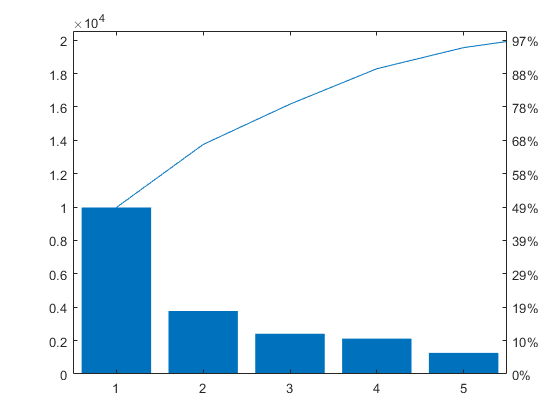

pareto(e)

    12.2. Visualize the transformed data in three dimensions by making a scatter plot of the data in the first three components.

fprintf("three components scatter plot by Multidimensional scaling.")

three components scatter plot by Multidimensional scaling.

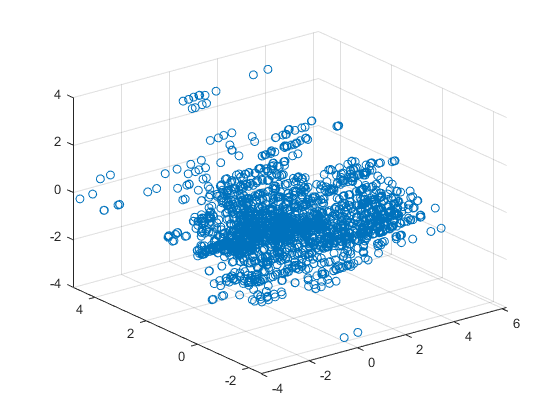

scatter3(X(:,1),X(:,2),X(:,3))

### 13. Principal Component Analysis (8 = 5 + 3)

    13.1. Transform `carDataNumericNorm` with PCA and visualize the importance of the components with a Pareto plot. 

[pcs,scrs,~,~,pexp] = pca(dataset3)

pcs =     0.4887   -0.0685    0.0395    0.0474   -0.2268   -0.1451   -0.5208   -0.6395
    0.4170    0.4049   -0.0556   -0.1906   -0.2262   -0.1562   -0.3450    0.6543
    0.4233   -0.2081    0.1853    0.0329   -0.1008    0.8405    0.1152    0.1109
    0.0143    0.5239    0.4165    0.6987    0.2429    0.0423   -0.0471   -0.0252
   -0.1898   -0.0276    0.8600   -0.4100   -0.2093   -0.1068   -0.0109   -0.0120
    0.4750    0.0933    0.0392    0.0446   -0.2275   -0.3446    0.7622   -0.1032
    0.3698   -0.0965    0.1276   -0.3013    0.8552   -0.1242   -0.0072    0.0093
   -0.0975    0.7034   -0.1735   -0.4597    0.0366    0.3175    0.1145   -0.3729


scrs =    -3.4365    0.3659    1.7266    2.9698    0.0323   -0.2024    0.2136    0.1941
   -3.4256    0.3631    1.7303    2.9610    0.0573   -0.2060    0.2134    0.1944
   -3.3291   -0.7452   -0.3409    0.1517   -0.3591   -0.5303    0.2732    0.0794
   -3.2902   -0.7553   -0.3275    0.1200   -0.2693   -0.5433    0.2725    0.0804
   -3.0001   -0.8310   -0.2274   -0.1163    0.4016   -0.6408    0.2668    0.0877
   -2.9787   -0.8366   -0.2200   -0.1337    0.4511   -0.6479    0.2664    0.0882
   -3.5208    0.1758   -0.2613    0.7736   -0.1282   -0.5532    0.2802   -0.0530
   -3.5149    0.1742   -0.2593    0.7688   -0.1147   -0.5552    0.2800   -0.0529
   -3.5018    0.1708   -0.2548    0.7581   -0.0842   -0.5596    0.2798   -0.0525
   -3.6795    0.1437    0.5660    0.3649   -0.2764   -0.6625    0.2693   -0.0639


pexp =    48.5608
   18.3685
   11.7514
   10.3190
    6.1597
    3.5528
    1.0336
    0.2541


fprintf("theree components scatter plot by pca.")

theree components scatter plot by pca.

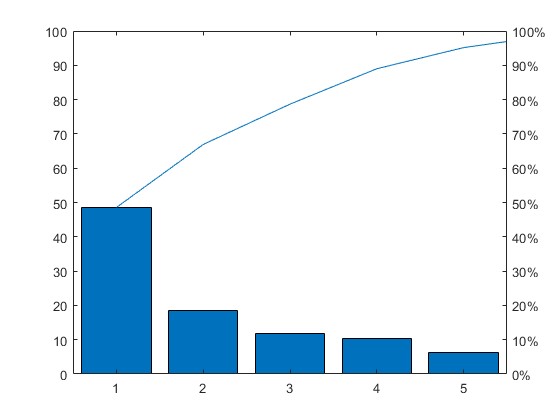

pareto(pexp)

    13.2. Visualize the transformed data in three dimensions by making a scatter plot of the data in the first three components.

scatter3(scrs(:,1),scrs(:,2),scrs(:,3))

### 14. K-means clustering (10 = 7 + 3)

rng(1234)

    14.1. Cluster `carDataNumericNorm` into 2 groups by k-means. Perform the clustering five times by specifying the k-means option in order to obtain the best result.

fprintf("Show kmeans approach when group number is 2.")

Show kmeans approach when group number is 2.

[g,c] = kmeans(dataset3,2,"Replicates",5)

g =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


c =    -0.6894   -0.5110   -0.6067    0.0507    0.2337   -0.6400   -0.4962    0.2212
    0.9980    0.7398    0.8783   -0.0734   -0.3383    0.9265    0.7183   -0.3202


    14.2. Visualize the clustering result in three dimensions by making a scatter plot of the data in the first three components that were obtained by PCA

fprintf("theree components scatter plot by pca.Therefor use 'scrs' for plotting.")

theree components scatter plot by pca.Therefor use 'scrs' for plotting.

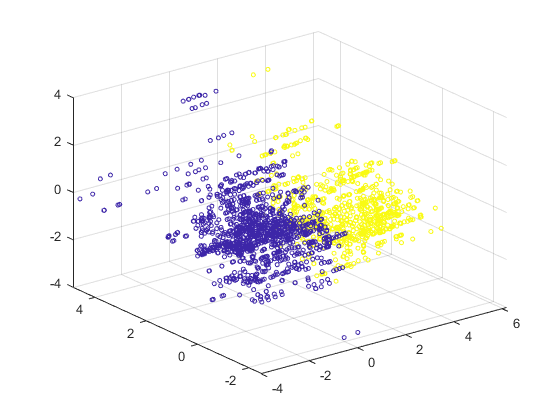

scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,g)

### 15. Gaussian Mixture Model clustering (10 = 7 + 3)

rng(1234)

    15.1. Cluster `carDataNumericNorm `into 2 groups by GMM. Perform the clustering five times by specifying the GMM option in order to obtain the best result.

gm = fitgmdist(dataset3,2,"Replicates",5,"RegularizationValue",0.02,"CovarianceType","diagonal")

gm = 

8개 차원에 2개 성분을 갖는 가우스 혼합 분포




fprintf("Perform cluster 5 times with RegularizationValue as 0.02 and see the result.")

Perform cluster 5 times with RegularizationValue as 0.02 and see the result.

[g,~,p] = cluster(gm,dataset3)

g =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


p =     1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000


    15.2. Visualize the clustering result in three dimensions by making a scatter plot of the data in the first three components that were obtained by Multidimesional scaling

fprintf("three components scatter plot by Multidimensional scaling.Not by pca. But grouped by g that we obtained from kmeans approach.")

three components scatter plot by Multidimensional scaling.Not by pca. But grouped by g that we obtained from kmeans approach.

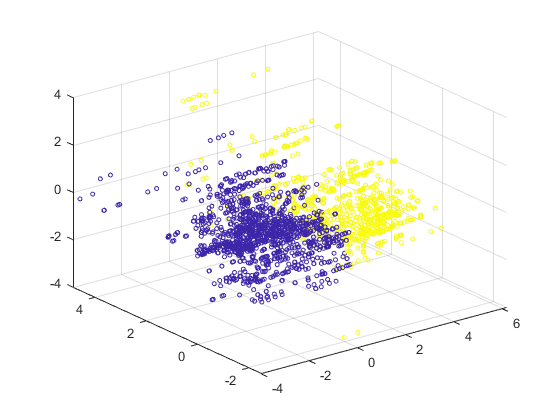

scatter3(X(:,1),X(:,2),X(:,3),10,g)

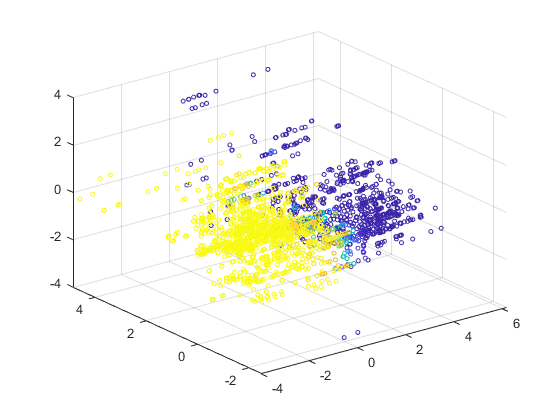

%just in case if someone want possibilty ver plot..
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,p(:,1))

### 16. Evaluating clusters (8)

Find the optimal number of clusters in `carDataNumericNorm.`

Conditions:

- Find the optimal number of clusters by **Hierarchical Clustering**.

- Use **'silhouette'** evaluation criterion.

- The number of clusters to evaluate is **2~5**.

fprintf("Since it wants 'Hierarchical Clustering' (not kmeans nor gmc), we must use linkage.")

Since it wants 'Hierarchcal Clustering' (not kmeans nor gmc), we must use linkage.

z = linkage(dataset3,"ward")

z = 	1.0e+03 *

    0.0390    0.0400         0
    0.0760    0.0770         0
    0.0180    0.0190         0
    0.0350    0.0360         0
    0.0270    0.0280         0
    0.0370    0.0380         0
    0.0410    0.0420         0
    0.0470    0.0480         0
    0.0890    0.0900         0
    0.1120    0.1130         0


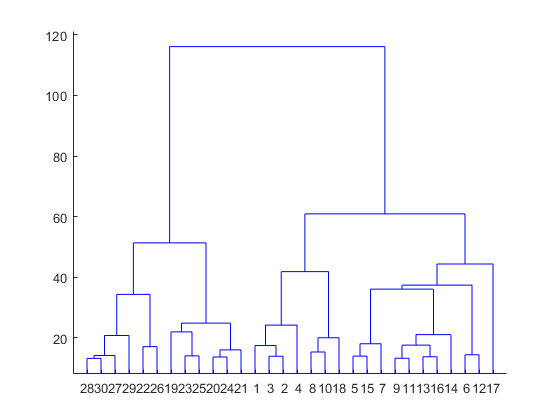

dendrogram(z)

fprintf("Now, we have to evaluate the number of clusters for Hierachcal Clustering.")

Now, we have to evaluate the number of clusters for Hierachcal Clustering.

clusterEV1 = evalclusters(dataset3,"linkage","CalinskiHarabasz","KList",2:5)

clusterEV1 =   CalinskiHarabaszEvaluation - 속성 있음:

    NumObservations: 2570
         InspectedK: [2 3 4 5]
    CriterionValues: [1.2536e+03 923.0623 797.5144 724.3137]
           OptimalK: 2


clusterEV2 = evalclusters(dataset3,"linkage","silhouette","KList",2:5)

clusterEV2 =   SilhouetteEvaluation - 속성 있음:

    NumObservations: 2570
         InspectedK: [2 3 4 5]
    CriterionValues: [0.4941 0.3161 0.3121 0.3336]
           OptimalK: 2


clusterEV3 = evalclusters(dataset3,"linkage","gap","KList",2:5)

clusterEV3 =   GapEvaluation - 속성 있음:

    NumObservations: 2570
         InspectedK: [2 3 4 5]
    CriterionValues: [1.5923 1.6082 1.6113 1.6486]
           OptimalK: 5


fprintf("Finally, we use 'silhouette' to evaluation criterion.")

Finally, we use 'silhouette' to evaluation criterion.

fprintf("case1 when cluster number is 2.")

case1 when cluster number is 2.

gc1 = cluster(z,"maxclust",2)

gc1 =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


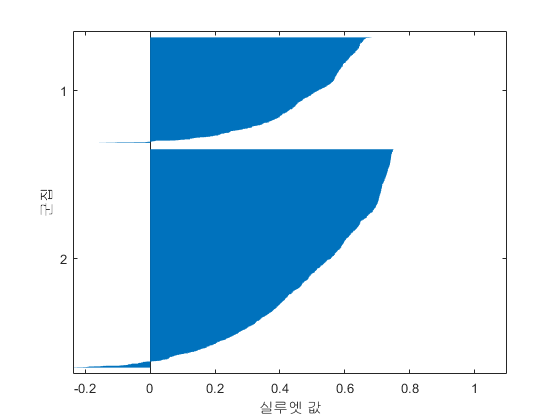

silhouette(dataset3,gc1)

fprintf("case2 when cluster number is 3.")

case2 when cluster number is 3.

gc1 = cluster(z,"maxclust",3)

gc1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


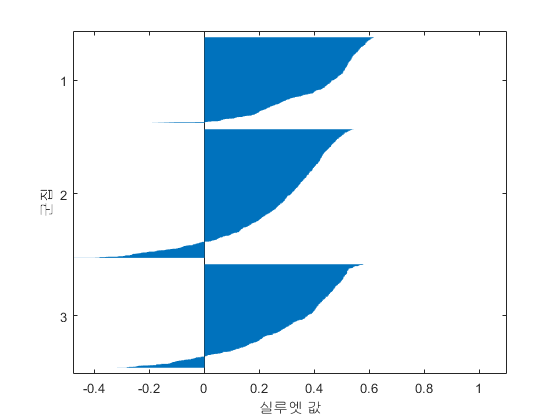

silhouette(dataset3,gc1)

fprintf("case3 when cluster number is 4.")

case3 when cluster number is 4.

gc1 = cluster(z,"maxclust",4)

gc1 =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


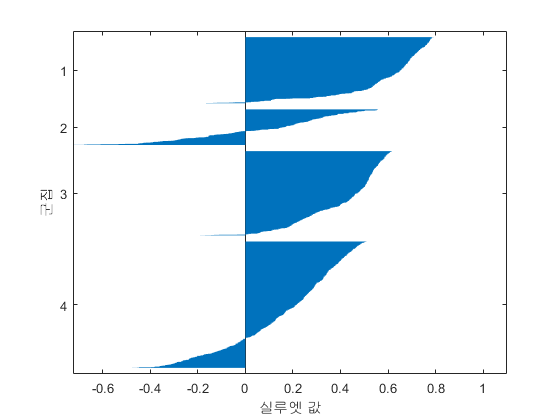

silhouette(dataset3,gc1)

fprintf("case4 when cluster number is 5.")

case4 when cluster number is 5.

gc1 = cluster(z,"maxclust",5)

gc1 =      5
     5
     5
     5
     5
     5
     5
     5
     5
     5


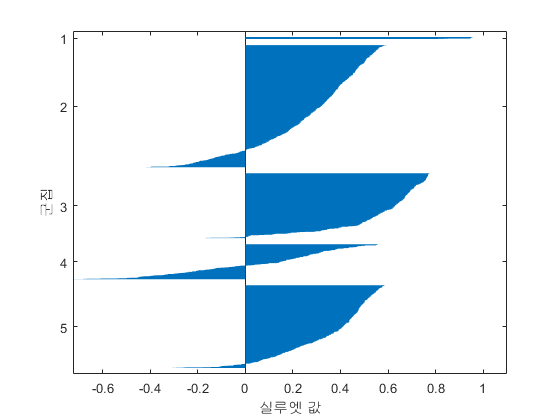

silhouette(dataset3,gc1)